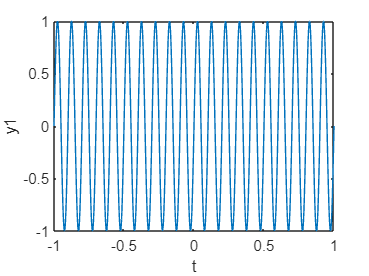

%Question 1:
%Part 1
t = linspace(-1,1,1000);
a = 1 + mod(30,3);
y1 = sin(20*pi*a*t);
plot(t,y1)
xlabel('t')
ylabel('y1')

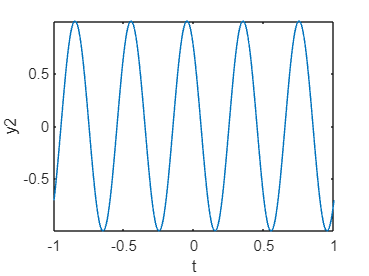

%Part 2
y2 = cos((5*pi*a*t) + (pi/4));
plot(t, y2)
xlabel('t')
ylabel('y2')

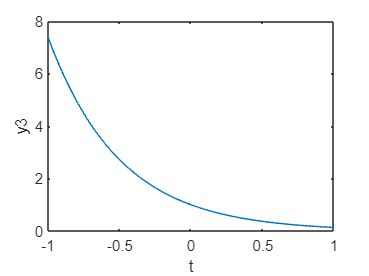

%Part 3
y3 = exp(-2*a*t);
plot(t, y3)
xlabel('t')
ylabel('y3')

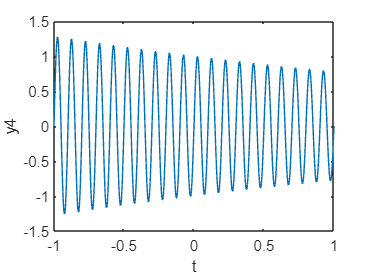

%Part 4
y4 = exp(-0.25*a*t).*sin(20*pi*t);
plot(t, y4)
xlabel('t')
ylabel('y4')

%Question 2:
t = linspace(-5,5,100000);
hold on  

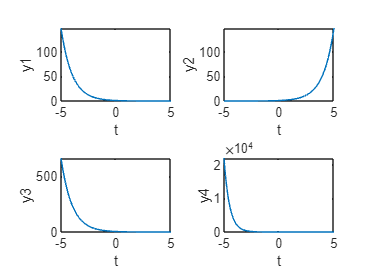

subplot(2,2,1)
y1 = inline("exp(-a*t)","t","a");
plot(t, y1(t,a))
xlabel('t')
ylabel('y1')

subplot(2,2,2)
y2 = inline("exp(a*t)", "t","a");
plot(t, y2(t,a))
xlabel('t')
ylabel('y2')

subplot(2,2,3)
y3 = inline("exp(-a*(t-1.5*a))", "t","a");
plot(t, y3(t,a))
xlabel('t')
ylabel('y3')

subplot(2,2,4)
y4 = inline("exp(-a*(2*a*t))", "t","a");
plot(t, y4(t,a))
xlabel('t')
ylabel('y4')
hold off

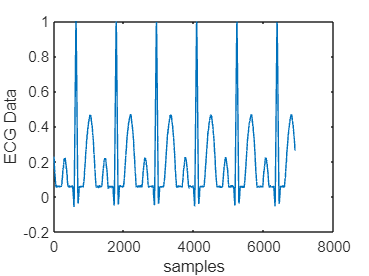

%Question 3:
A=load('ECG_Data.txt');
subplot(1,1,1)
plot(A)
xlabel('samples')
ylabel('ECG Data')

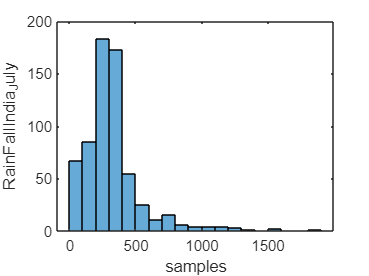

july = load('RainFallIndia_July.txt');
jan = load('RainFallIndia_Jan.txt');

figure; histogram(july)
xlabel('samples')
ylabel('RainFallIndia_July')

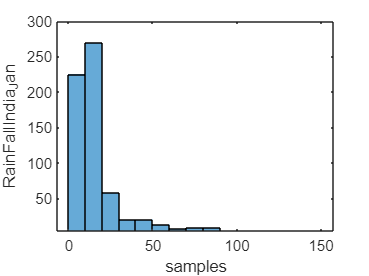

figure; histogram(jan)
xlabel('samples')
ylabel('RainFallIndia_Jan')


mean(july)

ans = 326.0936

mean(jan)

ans = 18.3513


std(july)

ans = 221.5326

std(jan)

ans = 21.0991

[s,Fs] = audioread('Track001.wav');
sound(s,Fs);

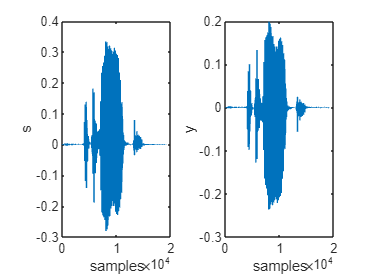

%Question 4:
[s,Fs] = audioread('speech.wav');
sound(s,Fs);
F = 250000* a;
y = s*cos(2*pi*(F/Fs));
audiowrite('y.wav', y, Fs);
[y,Fs] = audioread('y.wav');
sound(y,Fs)
subplot(1,2,1)
plot(s)
xlabel('samples')
ylabel('s')
subplot(1,2,2)
plot(y)
xlabel('samples')
ylabel('y')

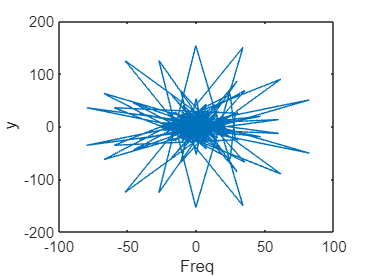

Fourier = fft(y);
subplot(1,1,1)
plot(Fourier)
xlabel('Freq')
ylabel('y')

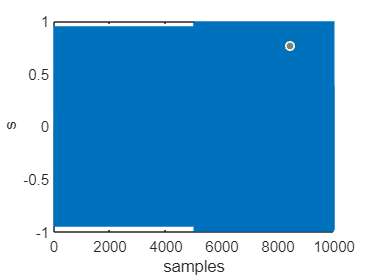

%Question 5:
t =[0:0.001:5];
fs = 5000;
y1 = sin(2*pi*200*a*t);
y2 = sin(2*pi*220*a*t);
k = [y1 y2];
audiowrite('sg2.wav', k, fs);
[s,Fs] = audioread('sg2.wav');
sound(s, Fs)
plot(s)
xlabel('samples')
ylabel('s')

%Question 6:
t = linspace(0,5,20000);

ans = 20000

fs = 44100;
y1 =  sin(220*t);
sound(y1, fs)

y2 = sin(246.94*t)

y2 =          0    0.0617    0.1232    0.1842    0.2444    0.3038    0.3620    0.4188    0.4741    0.5275    0.5789    0.6281    0.6749    0.7192    0.7607    0.7993    0.8348    0.8672    0.8963    0.9219    0.9441    0.9626    0.9775    0.9886    0.9960    0.9996    0.9994    0.9954    0.9876    0.9760    0.9607    0.9417    0.9192    0.8931    0.8637    0.8309    0.7950    0.7561    0.7142    0.6697    0.6226    0.5731    0.5215    0.4678    0.4124    0.3554    0.2971    0.2376    0.1772    0.1162


sound(y2, fs)

y3 = sin(261.63*t)

y3 =          0    0.0654    0.1304    0.1950    0.2587    0.3213    0.3825    0.4420    0.4997    0.5553    0.6085    0.6590    0.7068    0.7515    0.7930    0.8311    0.8657    0.8966    0.9236    0.9467    0.9657    0.9806    0.9913    0.9978    1.0000    0.9979    0.9916    0.9810    0.9662    0.9473    0.9243    0.8974    0.8666    0.8322    0.7942    0.7527    0.7081    0.6604    0.6099    0.5568    0.5014    0.4437    0.3842    0.3230    0.2605    0.1968    0.1323    0.0672    0.0019   -0.0635


sound(y3, fs)

y4 = sin(293.66*t)

y4 =          0    0.0734    0.1463    0.2185    0.2895    0.3589    0.4264    0.4916    0.5542    0.6137    0.6700    0.7226    0.7714    0.8160    0.8562    0.8918    0.9226    0.9484    0.9691    0.9846    0.9948    0.9996    0.9990    0.9931    0.9818    0.9652    0.9434    0.9165    0.8847    0.8481    0.8070    0.7615    0.7119    0.6585    0.6015    0.5413    0.4781    0.4124    0.3445    0.2747    0.2034    0.1310    0.0580   -0.0154   -0.0887   -0.1615   -0.2335   -0.3042   -0.3732   -0.4403


sound(y4, fs)

y5 = sin(329.63 *t)

y5 =          0    0.0823    0.1641    0.2447    0.3237    0.4005    0.4746    0.5454    0.6126    0.6755    0.7339    0.7874    0.8354    0.8778    0.9143    0.9445    0.9684    0.9856    0.9962    1.0000    0.9970    0.9873    0.9708    0.9478    0.9183    0.8826    0.8409    0.7935    0.7407    0.6828    0.6204    0.5537    0.4833    0.4096    0.3331    0.2544    0.1739    0.0922    0.0100   -0.0724   -0.1543   -0.2351   -0.3143   -0.3914   -0.4658   -0.5370   -0.6047   -0.6682   -0.7272   -0.7812


sound(y5, fs)

y6 = sin(349.23*t)

y6 =          0    0.0872    0.1737    0.2590    0.3422    0.4228    0.5002    0.5738    0.6431    0.7074    0.7663    0.8194    0.8663    0.9066    0.9399    0.9661    0.9849    0.9963    1.0000    0.9961    0.9846    0.9657    0.9394    0.9059    0.8655    0.8185    0.7653    0.7062    0.6418    0.5725    0.4988    0.4213    0.3407    0.2574    0.1721    0.0856   -0.0016   -0.0888   -0.1753   -0.2605   -0.3437   -0.4243   -0.5017   -0.5752   -0.6443   -0.7086   -0.7674   -0.8204   -0.8671   -0.9072


sound(y6, fs)

y7 = sin(392*t)

y7 =          0    0.3820    0.7061    0.9231    1.0000    0.9252    0.7101    0.3872    0.0056   -0.3769   -0.7021   -0.9209   -1.0000   -0.9273   -0.7140   -0.3924   -0.0112    0.3717    0.6982    0.9187    0.9999    0.9294    0.7179    0.3975    0.0168   -0.3665   -0.6941   -0.9165   -0.9998   -0.9314   -0.7218   -0.4026   -0.0224    0.3613    0.6901    0.9142    0.9997    0.9335    0.7256    0.4077    0.0280   -0.3560   -0.6860   -0.9120   -0.9995   -0.9355   -0.7295   -0.4128   -0.0335    0.3508


sound(y7, fs)

z = [y3 y4 y5 y6 y7 y1 y2]

z =          0    0.0654    0.1304    0.1950    0.2587    0.3213    0.3825    0.4420    0.4997    0.5553    0.6085    0.6590    0.7068    0.7515    0.7930    0.8311    0.8657    0.8966    0.9236    0.9467    0.9657    0.9806    0.9913    0.9978    1.0000    0.9979    0.9916    0.9810    0.9662    0.9473    0.9243    0.8974    0.8666    0.8322    0.7942    0.7527    0.7081    0.6604    0.6099    0.5568    0.5014    0.4437    0.3842    0.3230    0.2605    0.1968    0.1323    0.0672    0.0019   -0.0635


audiowrite('sg1.wav', z, fs);

[s,Fs] = audioread('sg1.wav');
sound(s, Fs)

%Question 7:
con = load('ConvFile1.txt')

con =    -0.0000
    0.0000
    0.0001
    0.0001
    0.0002
    0.0002
    0.0003
    0.0003
    0.0003
    0.0003


[s,Fs] = audioread('Track001.wav');
sound(s, Fs)
res = conv2(s, con)

res =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


audiowrite('conv.wav', res, Fs);
sound(res, Fs)

